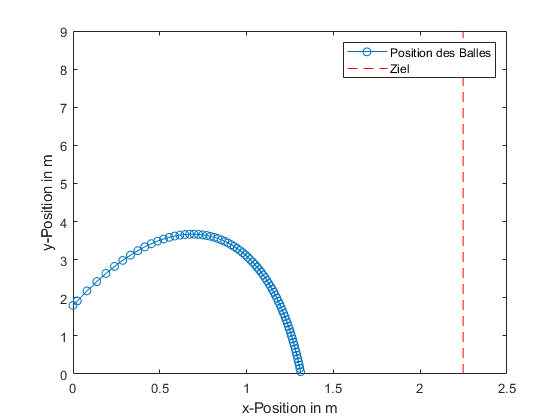

clc
clear all
run main.mlx

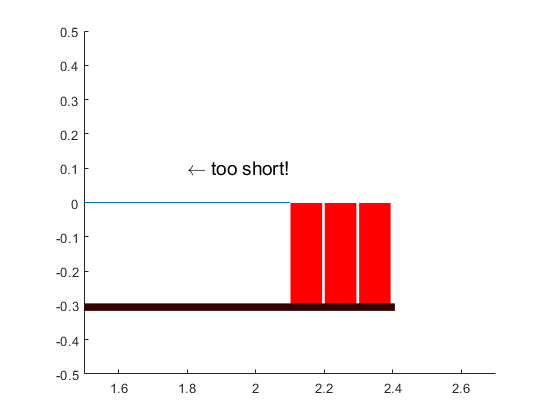


soly_new= sol.y(2,:); %extracting solution fom sol.y matrix
soly_new=soly_new(soly_new>0); %cutting solution vector to stop animation when ball passes cup level

solx_new= sol.x;

solx_new(:,length(soly_new)+1:end)=[]; %matching x vector size to y vector size

distance_t= interp1(soly_new,solx_new,0,"linear", "extrap"); % travelled distance when passing the top level of the cups

%adding extrapolated value at cup level so animation stops at cup level
soly_new(end+1)=0;
solx_new(end+1) = distance_t;





figure

%plot axis limits and scaling
xlim([0,max(sol.x)]);
ylim([-0.5, max(sol.y(2,:))+0.5]);
daspect([1,1,1]);

%added parameters
h_becheranim=0.3; %cup-height for animation
danim = par.d_Ball;
ranim = danim/2;


%ball
h = rectangle('Position',[solx_new(1)-ranim soly_new(1)-ranim danim danim],'Curvature',[1,1]);
h.LineWidth = 3;

%cups 
cup1_anim = rectangle("Position",[par.l 0-h_becheranim par.d_Becher h_becheranim] );
cup2_anim = rectangle("Position",[par.l+par.s_Becher+par.d_Becher 0-h_becheranim par.d_Becher h_becheranim] );
cup3_anim = rectangle("Position",[par.l+2*par.s_Becher+2*par.d_Becher 0-h_becheranim par.d_Becher h_becheranim] );
cup1_anim.EdgeColor = "w";
cup2_anim.EdgeColor = "w";
cup3_anim.EdgeColor = "w";
cup1_anim.FaceColor = "r";
cup2_anim.FaceColor = "r";
cup3_anim.FaceColor = "r";


%Tabletop
tabletop_anim = rectangle("Position",[0 -0.01-h_becheranim par.l+3*par.s_Becher+3*par.d_Becher 0.01]);
tabletop_anim.EdgeColor = [0.2 0 0];
tabletop_anim.FaceColor = [0.2 0 0];
tabletop_anim.LineWidth = 3;

%trajectory
a_line =animatedline;




% animation of Ball and trajectory
for m =  2:length(solx_new)
    h.Position = [solx_new(m)-ranim;soly_new(m)-ranim;danim;danim];
   
    addpoints(a_line,solx_new(m),soly_new(m));
    drawnow
   
    pause(1/length(soly_new));
      
end

% event information
pause (0.1)

if distance_t >= par.l+3*par.s_Becher+3*par.d_Becher %too short event
   t_line= line([par.l+3*par.s_Becher+3*par.d_Becher,distance_t],[0,0]);
   txt = '\rightarrow too far!';
   message = text(2.2,0.1,txt);
   message.FontSize=14;
   
elseif distance_t <= par.l %too far event
    t_line= line([par.l,distance_t],[0,0]);
    txt = '\leftarrow too short!';
    message = text(1.8,0.1,txt);
    message.FontSize=14;
   
else
    txt = 'good throw!'; %within cup range event
    message = text(2,0.1,txt);
    message.FontSize=14;
    
end


% zoomed in Result
pause(0.1)
xlim([1.5 2.7])
ylim([-0.5 0.5])